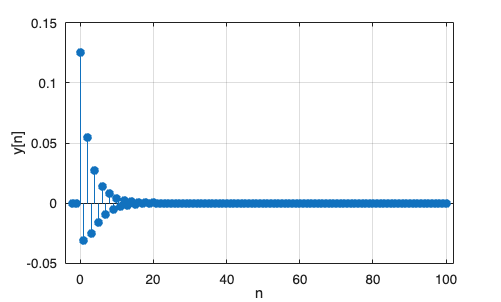

%2.25(c)
n = -2:100;
u = (n>=0);

y = (3/40)*((-3/4).^n).*u + (1/20)*((1/2).^n).*u;

stem(n, y, 'filled');
xlabel('n');
ylabel('y[n]');
grid on;

saveas(gcf, 'Q2_25c.png');

Q2

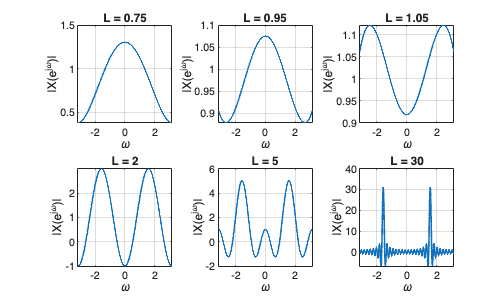

% 2.47(c)
clear; clc;

omega0 = pi/2;   % given omega0
omega = linspace(-pi, pi, 2000); 
L_values = [0.75, 0.95, 1.05, 2, 5, 30];  % selected L values
W = @(w,L) sin((2*L+1)*w/2)./sin(w/2);

figure;
for k = 1:length(L_values)
    L = L_values(k);

    X = 0.5*( W(omega - omega0, L) + W(omega + omega0, L) );

    subplot(2,3,k);
    plot(omega, X, 'LineWidth', 1.2);
    xlabel('\omega'); ylabel('|X(e^{j\omega})|');
    title(['L = ', num2str(L)]);
    grid on; xlim([-pi pi]);
end

saveas(gcf, 'X_dtft_grid.png');

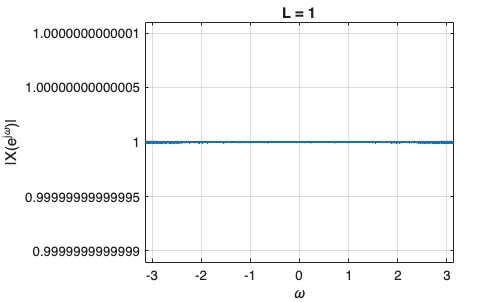



% Check when L = 1
L = 1; 
W = @(w,L) sin((2*L+1)*w/2)./sin(w/2);
X = 0.5*( W(omega - omega0, L) + W(omega + omega0, L) );

figure;
plot(omega, X, 'LineWidth', 1.5);
xlabel('\omega'); ylabel('|X(e^{j\omega})|');
title(['L = ', num2str(L)]);
grid on; xlim([-pi pi]);

saveas(gcf, 'X_dtft_L1.png');